# Data preprocessing for predicting metabolism from histone markers

## Get intersecting cell lines between datasets

clear all;
load ccle_metabolomics.mat;
load CCLE_Proteomics.mat gcp;

% Get intersecting cancer cell lines from dataset
[~, ia, ib] = intersect(gcp.Properties.RowNames, ...
                        metabolomics.Properties.RowNames);

% Matched cancer cell lines
celllines = string(gcp.Properties.RowNames(ia));
                    
% Proteomics
match_gcp = gcp(ia, :);
markers = string(gcp.Properties.VariableNames);

% Metabolomics
match_metab = metabolomics(ib, :); match_metab(:, "Tissue") = [];
metabolites = string(match_metab.Properties.VariableNames);
match_metab = table2array(match_metab);

% Remove histone markers with more than 50% of cancer cell lines containing
% missing values
match_gcp(:, [19, 39]) = [];

% Make dataset
X = table2array(match_gcp);
Y = zscore(double(match_metab));

% Get only metabolic histone markers
metabolic_subset = [2, 3, 4, ...        % H3K4
                    6, 7, 8, 9, ...     % H3K9
                    23, 27, 30, 32, ... % H3K27
                    20, 21, 22, ...     % H3K36
                    39, 40];            % H3K79
metabolic_gcp = match_gcp(:, metabolic_subset);
X_metab = table2array(metabolic_gcp);
Y_metab = Y;
save('~/Data/Models/eGEM/predict_metabolomics/predMetabolismFromGCP.mat')

### Sanity checks

% Sanity check
cmap = imresize(redbluecmap, [1000, 3]);
cmap = min(max(cmap,0), 1);

#### Boxplots

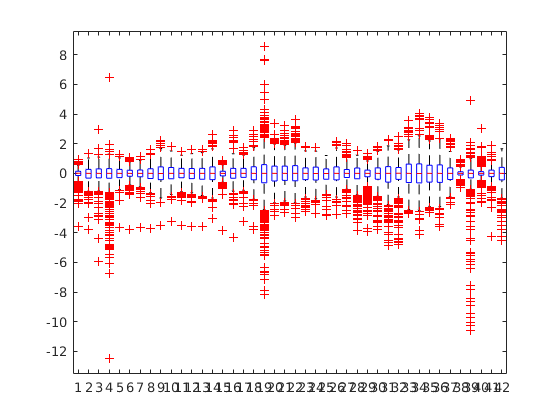

boxplot(X)

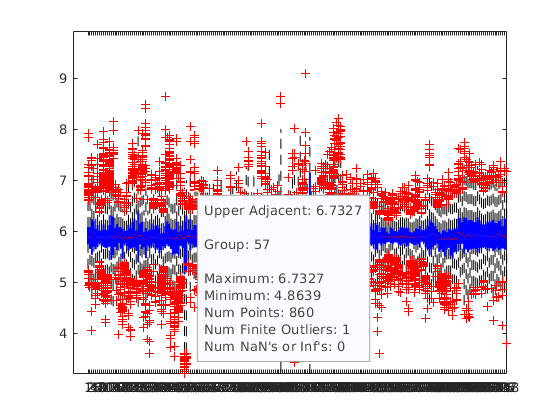

boxplot(Y)

#### Correlation matrix

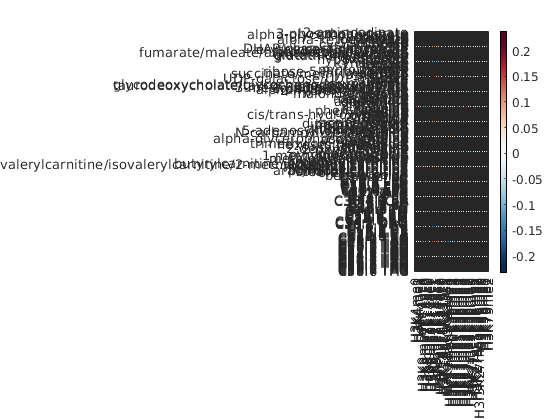

[rcorr, pcorr] = corr(X, Y);
heatmap(rcorr', ...
    'YDisplayLabel', metabolites', ...
    'XDisplayLabels', markers', ...
    'Colormap', cmap)